clc;
clear all;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4

%   DH  = [  a_n  alpha_n  d_n  theta_n]
% DHparameter=[0 0 0.04 0;
%              0.12 pi/2 0 13*pi/30;
%              0.194 0 0 -23*pi/30;
%              0 -pi/2 0.176 0;
%              0 pi/2 0 pi/2;
%              0 pi/2 0 0]

% DHparameter=[0 0 4 0;
%              12 pi/2 0 0;
%              19.4 0 0 0;
%              0 -pi/2 17.6 0;
%              0 pi/2 0 0;
%              0 pi/2 0 0]
% DHparameter=[0 pi/2 0.04 0;
%              0.12 0 0 13*pi/30+pi/2;
%              0.194 -pi/2 0 -23*pi/30+pi/2;
%              0 0 0.176 0;
%              0 pi/2 0 pi/2;
%              0 0 0 0;
%              0.2 0 0 0;
%              -0.05 pi/2 0 pi/2];
% DHparameter = [0 0 0 0;
%                0 -pi/2 0.082 0;
%                0.082 0 0 -pi/2;
%                0 pi/2 0 pi/2;
%                0 -pi/2 0.1412 0;
%                0 pi/2 0 -pi/2;
%                0 0 0.120 0]

DHparameter = [0 0 82 0;
               0 pi/2 0 pi/2;
               143.2 0 0 -pi/2;
               0 -pi/2 200 0;
               0 pi/2 0 pi/2;
               0 pi/2 0 0;
               25 0 0 0;
               0 0 25 0]

DHparameter =          0         0   82.0000         0
         0    1.5708         0    1.5708
  143.2000         0         0   -1.5708
         0   -1.5708  200.0000         0
         0    1.5708         0    1.5708
         0    1.5708         0         0
   25.0000         0         0         0
         0         0         0         0


## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",10,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
% joint1.PositionLimits = [0 2*pi];
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];

body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');

% joint2.HomePosition = 13*pi/30+pi/2;


body2.Mass = 10;
% body2.CenterOfMass = [0 0 0];


% joint2.PositionLimits = [-2*pi/3 0];
% 
body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;

% joint3.HomePosition = -23*pi/30+pi/2;
% joint3.PositionLimits = [-10 10]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 

% body3.CenterOfMass = [0 0 0];

% joint3.PositionLimits = [-pi/3 pi/3];

body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;


% joint4.PositionLimits = [0 2*pi];
                
body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');

% joint5.HomePosition = pi/2;
% joint5.PositionLimits = [-pi/4 pi/4];

% body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
% joint6.PositionLimits = [0 0.1];
% body6.Mass = 10;

% joint6.PositionLimits = [-pi/4 pi/4];

body7 =rigidBody('Body7');
joint7 = rigidBodyJoint('Joint7','fixed');

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 

body8 =rigidBody('Body8');
joint8 = rigidBodyJoint('Joint8','fixed');


setFixedTransform(joint1,DHparameter(1,:),"mdh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"mdh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"mdh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"mdh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"mdh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"mdh");
body6.Joint = joint6;

setFixedTransform(joint7,DHparameter(7,:),"mdh");
body7.Joint = joint7;

% setFixedTransform(joint8,DHparameter(8,:),"dh");
% body8.Joint = joint8;


addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');
addBody(dental,body7,'Body6');
% addBody(dental,body8,'Body7');


showdetails(dental)

--------------------
Robot: (7 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   Body7(7)  
   7        Body7        Joint7         fixed            Body6(6)   
--------------------


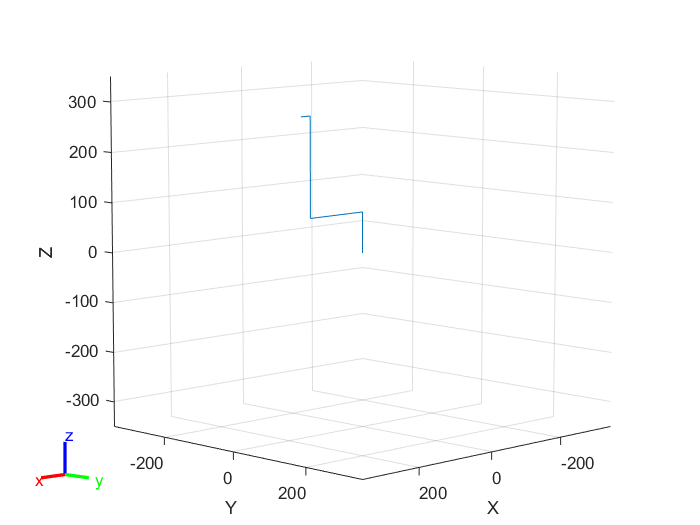

figure;
show(dental);

## `Denture, 3 - Teeth, 1 - Tooth, Final Tooth, Transformation and Shrink`

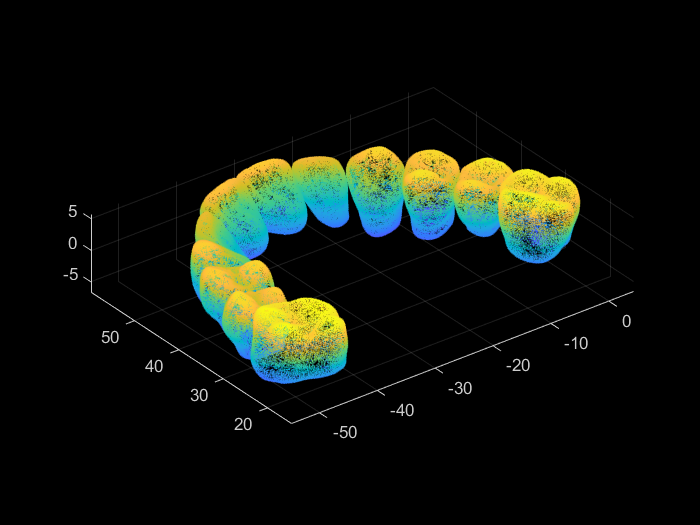

% Read and plot complete denture
stlData = stlread('stl/1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

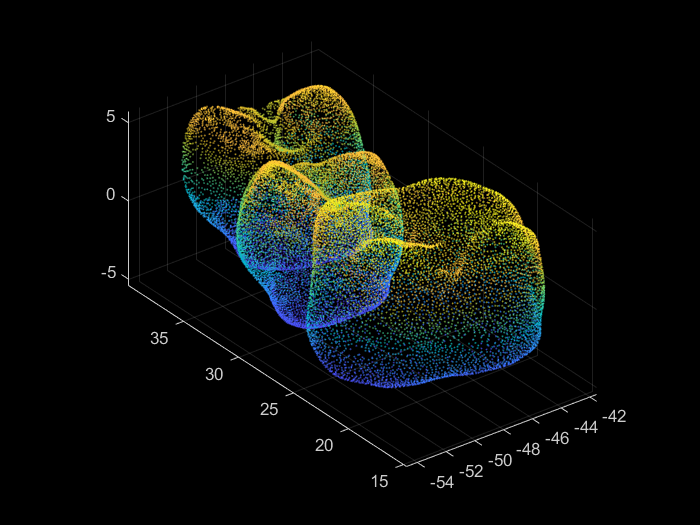


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

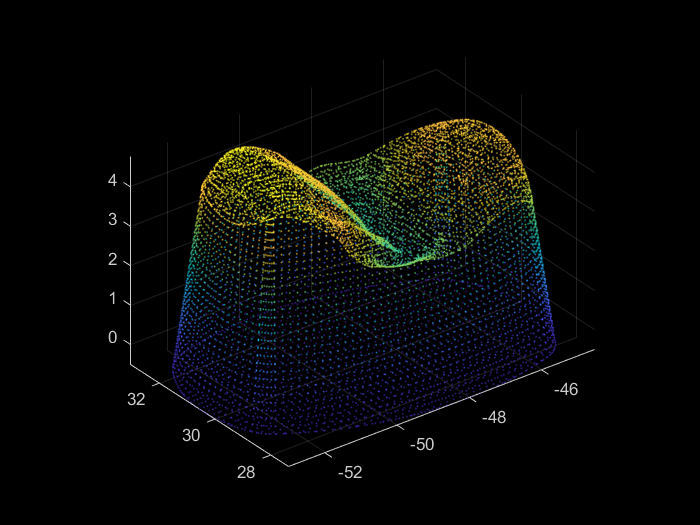


% Import and plot final model individually
stlData_fin = stlread("stl/1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

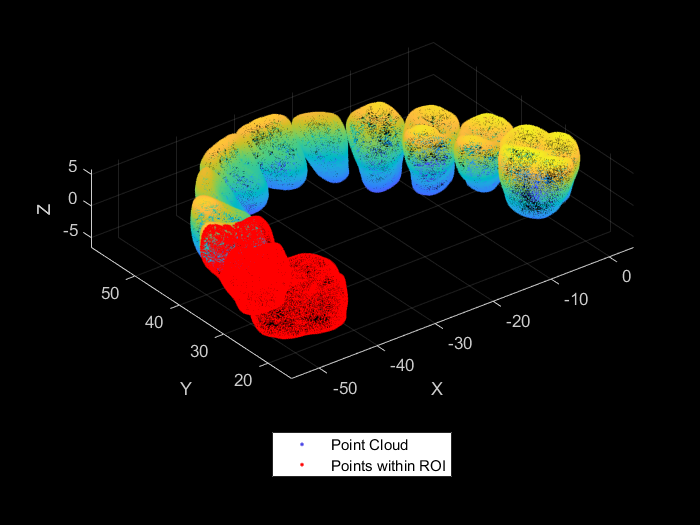


% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

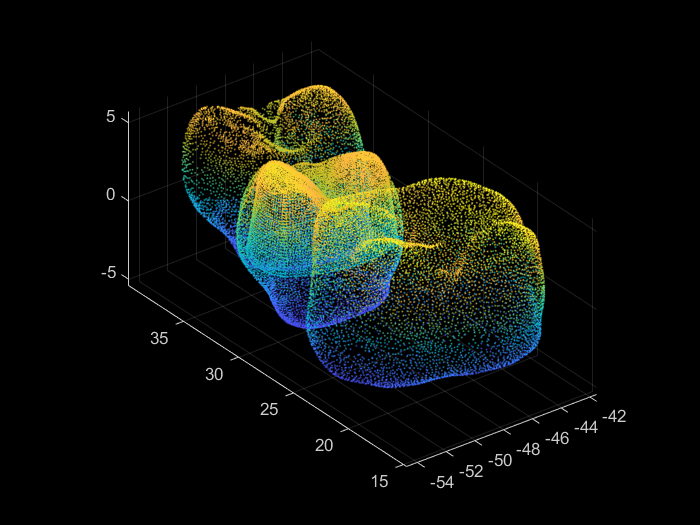


% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

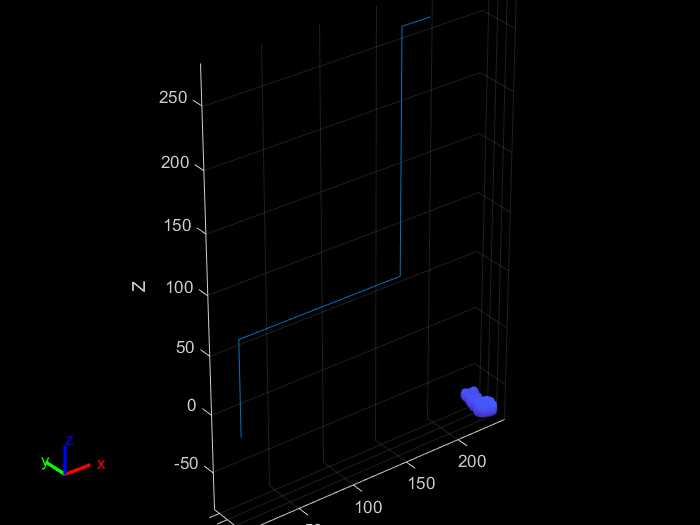


%Transformation (shrink and move)
Sx = 1.3;
Sy = 1.3;
Sz = 1.3;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -75;
trans = 1000*[0.300 -0.015 zCoord/1000];
% tform = rigid3d(rot,trans);
rigid_tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,rigid_tform);
ptCloud_fin = pctransform(ptCloud_fin,rigid_tform);

figure
show(dental);
hold on

pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')
pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')


% show(dental);

stlData = stlread('Single_Back_tooth.stl');
points = stlData.Points;
backTooth = pointCloud(points);

stlData = stlread('Single_front_tooth.stl');
points = stlData.Points;
frontTooth = pointCloud(points);

% frontTooth = pctransform(frontTooth,tform);
% frontTooth = pctransform(frontTooth,rigid_tform);

%Merge
neighboringTeeth = pcmerge(frontTooth, backTooth, 1);

%Transformation (shrink and move)
neighboringTeeth = pctransform(neighboringTeeth,tform);
neighboringTeeth = pctransform(neighboringTeeth,rigid_tform);


% pcshow(neighboringTeeth)
% xlabel('X'); ylabel('Y'); zlabel('Z')

## `Curves for end-effector path planning`

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.5

r = 0.5000

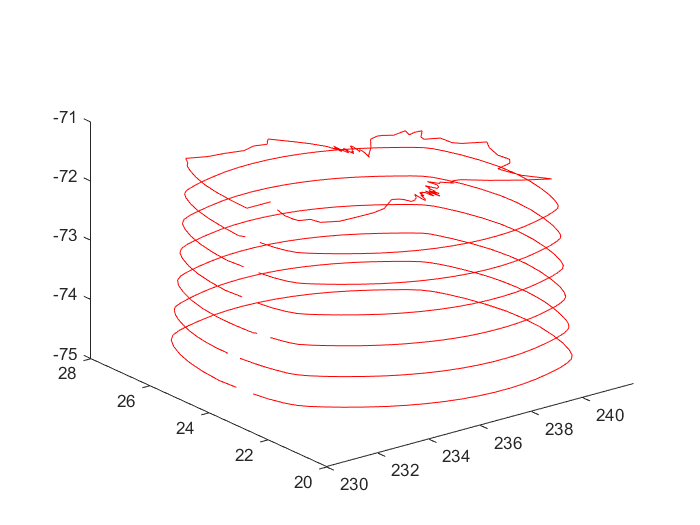

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],5);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.01);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

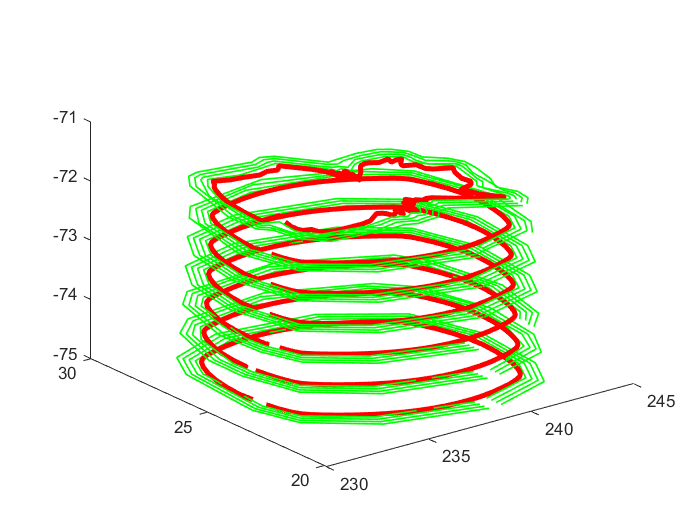

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.2*j);
        polyout.Vertices = downsample(polyout.Vertices,20);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {57×3 double}    {76×3 double}    {68×3 double}    {57×3 double}    {57×3 double}    {58×3 double}    {145×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 60×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 46×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 40×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    { 35×3 double}


% Row = Top to Bottom - Inside to Outside
% Column = Left to Right - Bottom to Top

## `Save all quarters in arrays`

curve1 = allPoints{5,1}

curve1 =   237.9255   19.8728  -74.7500
  233.6265   20.6280  -74.7500
  231.1622   22.0348  -74.7500
  230.5175   23.5365  -74.7500
  230.8811   26.6867  -74.7500
  231.7263   27.8323  -74.7500
  234.4792   28.5931  -74.7500
  238.8636   28.1596  -74.7500
  241.7712   26.7023  -74.7500
  242.7407   24.4631  -74.7500


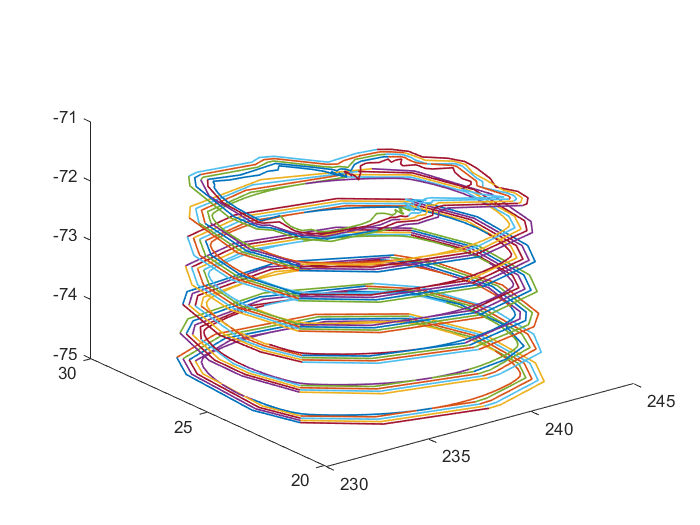

appendAllPoints = [];
figure

for i=1:7
    for j = 1:2 %Offsetting inner most contour fix
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q2;
        q2_arr{i,j} = q1;
        q3_arr{i,j} = q4;
        q4_arr{i,j} = q3;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
    for j=2:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q1;
        q2_arr{i,j} = q2;
        q3_arr{i,j} = q3;
        q4_arr{i,j} = q4;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
end

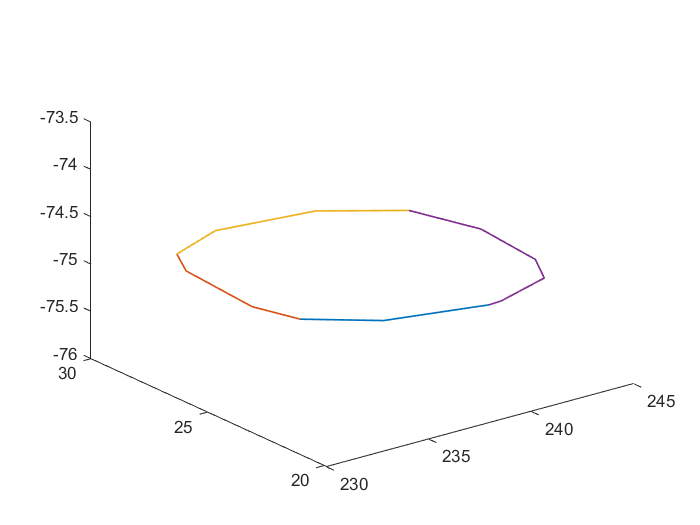

% Show a single curve.
figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);


% q2 is front
% q1 is right
% q3 is left
% q4 is back

## `Splitting Geometry and Forming into Trajectory`

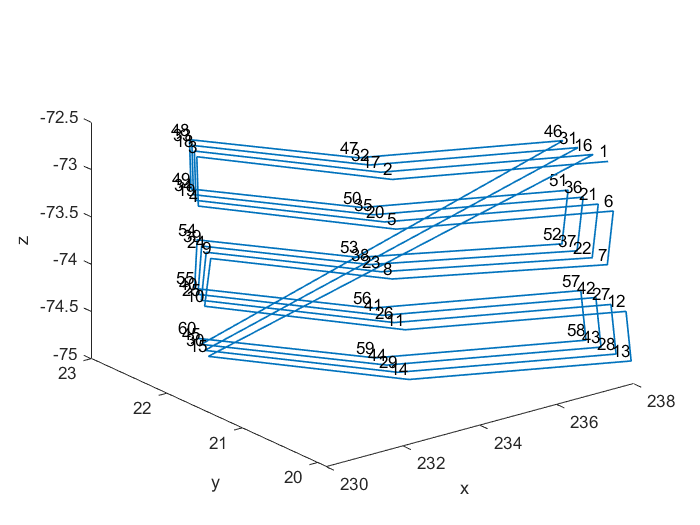

%Plot a single quarter
% figure
% for i=1:5
%     for j=1:5
%         plot3(q1_arr{i,j}(:,1),q1_arr{i,j}(:,2),q1_arr{i,j}(:,3),"LineWidth",1);hold on;
%     end
% end

q1_traj_arr = orderQuarter(q1_arr);
q2_traj_arr = orderQuarter(q2_arr);
q3_traj_arr = orderQuarter(q3_arr);
q4_traj_arr = orderQuarter(q4_arr);

q1_traj_arr_fixed = [];
for i = 1:60
    q1_traj_arr_fixed(i,:) = q1_traj_arr(i,:);
end

q2_traj_arr_fixed = [];
for i = 1:80
    q2_traj_arr_fixed(i,:) = q2_traj_arr(i,:);
end

q3_traj_arr_fixed = [];
for i = 1:80
    q3_traj_arr_fixed(i,:) = q3_traj_arr(i,:);
end

q4_traj_arr_fixed = [];
for i = 1:135
    q4_traj_arr_fixed(i,:) = q4_traj_arr(i,:);
end

save fixed_contour.mat q1_traj_arr_fixed q2_traj_arr_fixed q3_traj_arr_fixed q4_traj_arr_fixed

figure
plotQuarter(q1_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

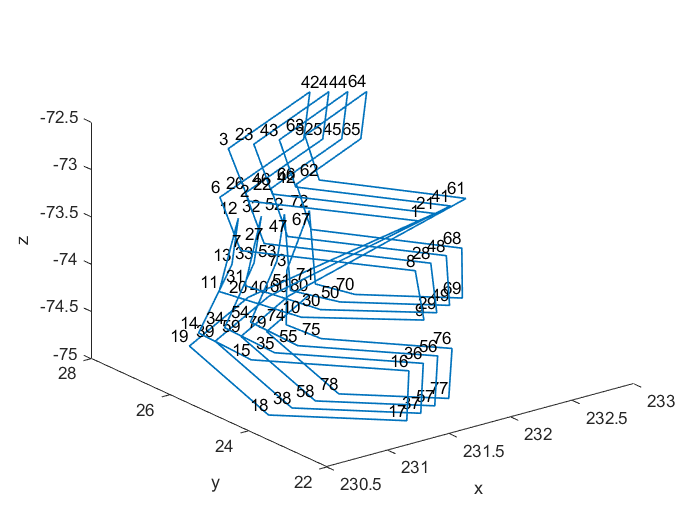

plotQuarter(q2_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

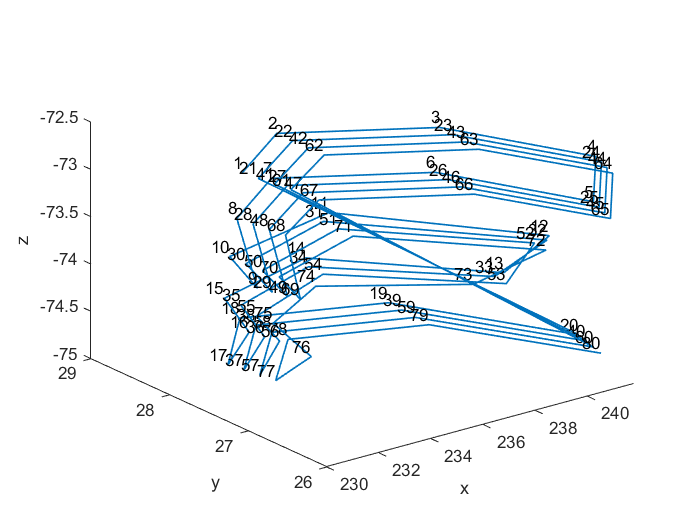

plotQuarter(q3_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

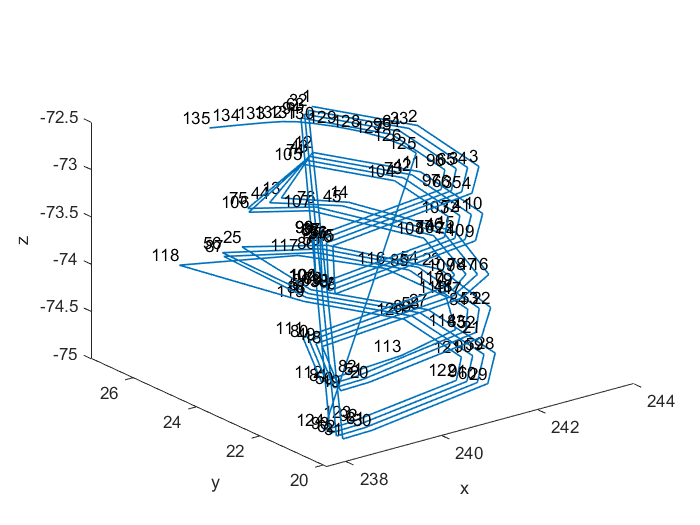

plotQuarter(q4_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
hold off

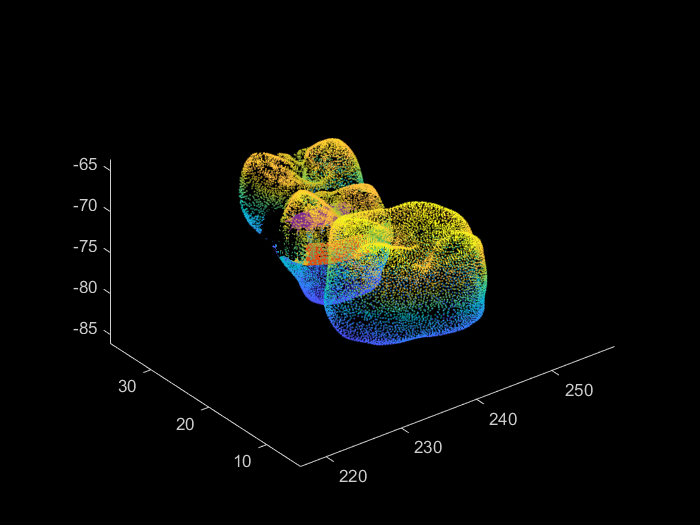


figure
hold on
pcshow(ptCloud_3t)
plotQuarter(q1_traj_arr_fixed);
plotQuarter(q2_traj_arr_fixed);
plotQuarter(q3_traj_arr_fixed);
plotQuarter(q4_traj_arr_fixed);

MSH = collisionMesh(ptCloud_fin.Location)

MSH =   collisionMesh with properties:

    Vertices: [10770×3 double]
        Pose: [4×4 double]


worldCollisionArray = {MSH}

worldCollisionArray = 1×1 cell array
    {1×1 collisionMesh}


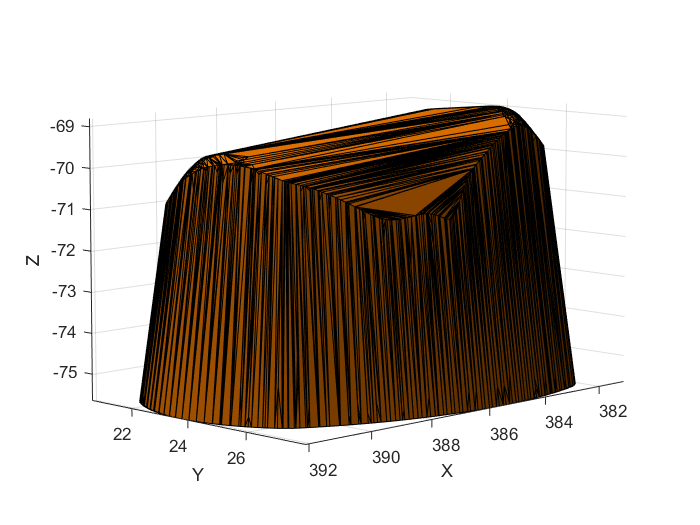

ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

## `Calculate IK for Trajectories`

T = [0 0 -1 0; 0 -1 0 0;-1 0 0 0;0 0 0 1];
ik = inverseKinematics("RigidBodyTree",dental);
weights = [1 1 1 1 1 1];
q0 = homeConfiguration(dental);
qinitial = q0;
ik.SolverParameters.MaxIterations = 450000;
ik.SolverParameters.MaxTime = 1000;
for i = 1:length(q1_traj_arr_fixed)
%     point = q1_traj_arr(i,:);
%     pose = trvec2tform(q1_traj_arr_fixed(i,:)); %*axang2tform([1 1 1 0]);
    pose = trvec2tform(q1_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q1_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 84
    NumRandomRestarts: 0
        PoseErrorNorm: 9.8383e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6026e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0970e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 51
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0918e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6684e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0964e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5693e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3716e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3493e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6912e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2427e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 55
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3715e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2906e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9928e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8522e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9092e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 50
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3161e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0715e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 52
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0495e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2600e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1082e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0856e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1161e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1204e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7303e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1618e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7286e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6497e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9616e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 6.8546e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9674e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3174e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 53
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2548e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 51
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3333e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1003e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4045e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 55
    NumRandomRestarts: 0
        PoseErrorNorm: 9.0171e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3338e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0904e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 53
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4029e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2971e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7145e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 52
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4398e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 54
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7607e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9947e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9464e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 55
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0192e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 54
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2921e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1151e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2561e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4586e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 54
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3576e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 52
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6875e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 54
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3159e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 55
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1795e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1959e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8610e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0708e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7108e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0915e-08
             ExitFlag: 1
               Status: 'success'


% pose = trvec2tform(q1_traj_arr_fixed(1,:))*T

q1_traj_arr_fixed(10,:)

ans =   231.2016   22.1047  -74.2500


getTransform(dental,q1_config(:,10),'Body7')

ans =     0.0000    0.0000   -1.0000  231.2016
    0.0000   -1.0000   -0.0000   22.1047
   -1.0000   -0.0000   -0.0000  -74.2500
         0         0         0    1.0000


weights = [0.4 0.4 0.4 1 1 1];
qinitial = q0;
for i = 1:length(q2_traj_arr_fixed)
%     pose = trvec2tform(q2_traj_arr_fixed(i,:))*axang2tform([1 1 1 pi]);
    pose = trvec2tform(q2_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q2_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 110
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1168e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2322e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7193e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2332e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0059e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2176e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1365e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 54
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7960e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9156e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7876e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9703e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3921e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 50
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5125e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1227e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3336e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5802e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3478e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0286e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2217e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6521e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2848e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8795e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1699e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0405e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3263e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8936e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3937e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6608e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8357e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 8.3188e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9408e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0904e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 55
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2217e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4275e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0859e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8444e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 52
    NumRandomRestarts: 0
        PoseErrorNorm: 9.0568e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6066e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 8.8441e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4365e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 6.8543e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2619e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 9.0736e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3322e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8589e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4382e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1715e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0141e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2195e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 9.1257e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9657e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7335e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4073e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9427e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8650e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0149e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6342e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9357e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8708e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9679e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2028e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 5.0219e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2111e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9936e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0752e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2741e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6521e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7103e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8020e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9618e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 9.4931e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6006e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4713e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8197e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4514e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7276e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 48
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6896e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 9.8343e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2029e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9071e-10
             ExitFlag: 1
               Status: 'success'


q2_config

q2_config =     0.0960    0.1061    0.1146    0.1192    0.1195    0.1148    0.1062    0.0958    0.0952    0.1008    0.1080    0.1177    0.1182    0.1098    0.1036    0.0953    0.0950    0.1018    0.1151    0.1195    0.0964    0.1062    0.1141    0.1184    0.1187    0.1143    0.1062    0.0963    0.0957    0.1011    0.1078    0.1171    0.1174    0.1094    0.1037    0.0958    0.0955    0.1018    0.1147    0.1188    0.0969    0.1062    0.1137    0.1176    0.1179    0.1138    0.1062    0.0967    0.0962    0.1014
   -1.3408   -1.3437   -1.3388   -1.3304   -1.3307   -1.3393   -1.3444   -1.3413   -1.3414   -1.3448   -1.3445   -1.3361   -1.3363   -1.3446   -1.3459   -1.3424   -1.3428   -1.3464   -1.3414   -1.3344   -1.3396   -1.3423   -1.3376   -1.3298   -1.3301   -1.3381   -1.3429   -1.3401   -1.3403   -1.3434   -1.3431   -1.3353   -1.3355   -1.3433   -1.3445   -1.3412   -1.3417   -1.3449   -1.3401   -1.3338   -1.3383   -1.3409   -1.3364   -1.3293   -1.3296   -1.3369   -1.3415   -1.3389   -1.3

getTransform(dental,q2_config(:,4),'Body7')

ans =     0.0000    0.0000   -1.0000  232.2218
    0.0000   -1.0000   -0.0000   27.8154
   -1.0000   -0.0000   -0.0000  -72.7500
         0         0         0    1.0000


ik.SolverParameters.MaxIterations = 45000;
ik.SolverParameters.MaxTime = 10;
weights = [0.3 0.3 0.3 1 1 1];
qinitial = q2_config(:,80);
for i = 1:length(q3_traj_arr_fixed)
%     pose = trvec2tform(q3_traj_arr_fixed(i,:))*axang2tform([1 1 1 pi]);
    pose = trvec2tform(q3_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q3_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5566e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 5.2265e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3084e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5812e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1861e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1097e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9550e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1453e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4860e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9824e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 9.4642e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7288e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7453e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6220e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9648e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6809e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3263e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6981e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7170e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3869e-09
             ExitFlag: 4
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0546e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1105e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1735e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 8.3236e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2400e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5999e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0109e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2107e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0612e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7143e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0386e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2550e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4368e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1078e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1274e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6800e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0357e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0689e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7395e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4069e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1068e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1483e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4400e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9291e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9202e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2088e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9920e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4568e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7808e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8019e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9162e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8439e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4072e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 6.8077e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3564e-08
             ExitFlag: 4
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 8.8907e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1851e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1802e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9327e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6212e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 73
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9918e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2879e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5256e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0700e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2610e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9416e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0438e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3955e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1972e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3226e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 5.1991e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5679e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2720e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3531e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9660e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8206e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5380e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3421e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2507e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9125e-09
             ExitFlag: 1
               Status: 'success'


getTransform(dental,q3_config(:,60),'Body7')

ans =     0.0000    0.0000   -1.0000  241.4883
   -0.0000   -1.0000   -0.0000   26.4195
   -1.0000    0.0000   -0.0000  -74.7500
         0         0         0    1.0000


ik.SolverParameters.MaxIterations = 45000;
ik.SolverParameters.MaxTime = 100;
qinitial = q3_config(:,80);
weights=[0.1 0.1 0.1 1 1 1]

weights =     0.1000    0.1000    0.1000    1.0000    1.0000    1.0000


for i = 1:length(q4_traj_arr_fixed)
%     pose = trvec2tform(q4_traj_arr_fixed(i,:))*axang2tform([1 1 1 0]);
    pose = trvec2tform(q4_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q4_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 75
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0483e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1412e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2504e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5965e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 73
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3770e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6860e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1922e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9384e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9495e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2474e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0953e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9702e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0137e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8525e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3265e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 9.8433e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1663e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6041e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4642e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9103e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1971e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0850e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3461e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4628e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8678e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4990e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6314e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8312e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3824e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 76
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4445e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9344e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2397e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8981e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1271e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0023e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0631e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7335e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5860e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 54
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8816e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1311e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3384e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 7.4079e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9557e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6391e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1955e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3743e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1967e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 74
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3852e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9337e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 8.3658e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0772e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9164e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3011e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3529e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7909e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 6.9679e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7695e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5185e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1024e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8274e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4314e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4856e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6962e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2573e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0473e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5509e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6252e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7688e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4472e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5253e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5647e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4824e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 8.3974e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0618e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8429e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5263e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 6.9090e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5606e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1237e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6332e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3315e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5742e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4140e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7970e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 74
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0004e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2156e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2594e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 7.3279e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7325e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 73
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8101e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6922e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2073e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2118e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3544e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 6.9790e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3040e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8393e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1386e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5466e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7653e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0860e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5148e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8952e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8212e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0114e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 0
        PoseErrorNorm: 7.3767e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8280e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7891e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1587e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1555e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 8.5086e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1157e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6261e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0208e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 73
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0222e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3121e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5678e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0620e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 9.1752e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5423e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8532e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7456e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1009e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 54
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2818e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1916e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3508e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1220e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7007e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 60
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2329e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9393e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5791e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0814e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7425e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3075e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 9.8365e-10
             ExitFlag: 1
               Status: 'success'


save q_configs q1_config q2_config q3_config q4_config;
% q_config = matfile('q_configs.mat');
% q1_config = q_config.q1_config;
% q1_config = trapveltraj(q1_config,length(q1_config(1,:)),"EndTime",2);


%Combine and add home config between
homeConfig = findHomeConfig(ptCloud_fin);
pose = trvec2tform(homeConfig);
home = ik("Body7",pose,weights,dental.homeConfiguration);
%Need to get traj between last config of each q and home, then add these
%trajs to q_tot
t = 20;
q_1tohome = trapveltraj([q1_config(:,length(q1_config(1,:))),home],t,"EndTime",2);
q_hometo2 = trapveltraj([home,q2_config(:,1)],t,"EndTime",2);
q_2tohome = trapveltraj([q2_config(:,length(q2_config(1,:))),home],t,"EndTime",2)

q_2tohome =     0.1173    0.1172    0.1172    0.1171    0.1169    0.1168    0.1166    0.1163    0.1161    0.1158    0.1156    0.1153    0.1151    0.1148    0.1146    0.1145    0.1143    0.1142    0.1142    0.1141
   -1.3325   -1.3330   -1.3346   -1.3372   -1.3409   -1.3456   -1.3513   -1.3579   -1.3645   -1.3711   -1.3778   -1.3844   -1.3910   -1.3976   -1.4033   -1.4080   -1.4117   -1.4143   -1.4159   -1.4164
   -0.2013   -0.1991   -0.1926   -0.1817   -0.1665   -0.1469   -0.1230   -0.0957   -0.0682   -0.0407   -0.0131    0.0144    0.0419    0.0692    0.0931    0.1127    0.1279    0.1388    0.1453    0.1475
   -1.2663   -1.2584   -1.2348   -1.1953   -1.1400   -1.0690   -0.9822   -0.8831   -0.7831   -0.6831   -0.5832   -0.4832   -0.3832   -0.2841   -0.1973   -0.1263   -0.0710   -0.0316   -0.0079    0.0000
   -0.1229   -0.1338   -0.1666   -0.2211   -0.2974   -0.3956   -0.5155   -0.6524   -0.7906   -0.9287   -1.0669   -1.2050   -1.3431   -1.4800   -1.6000   -1.6982   -1.7745   -1.8290   -

q_hometo3 = trapveltraj([home,q3_config(:,1)],t,"EndTime",2);
q_3tohome = trapveltraj([q3_config(:,length(q3_config(1,:))),home],t,"EndTime",2);
q_hometo4 = trapveltraj([home,q4_config(:,1)],t,"EndTime",2);


% q_tot = [q1_config ];
q_tot = [q1_config q2_config q3_config q4_config];

## `Finding the collision free trajectory`

% Need a mesh of the tooth
MSH = collisionMesh(ptCloud_fin.Location);
worldCollisionArray = {MSH};
robotCollision = isInCollision(q_tot, MSH, dental);
if ~robotCollision
    disp("The robot is in not in collision.")
else
    disp("The robot is in collision")
end

The robot is in not in collision.


## `Calculate and Plot Closest points`

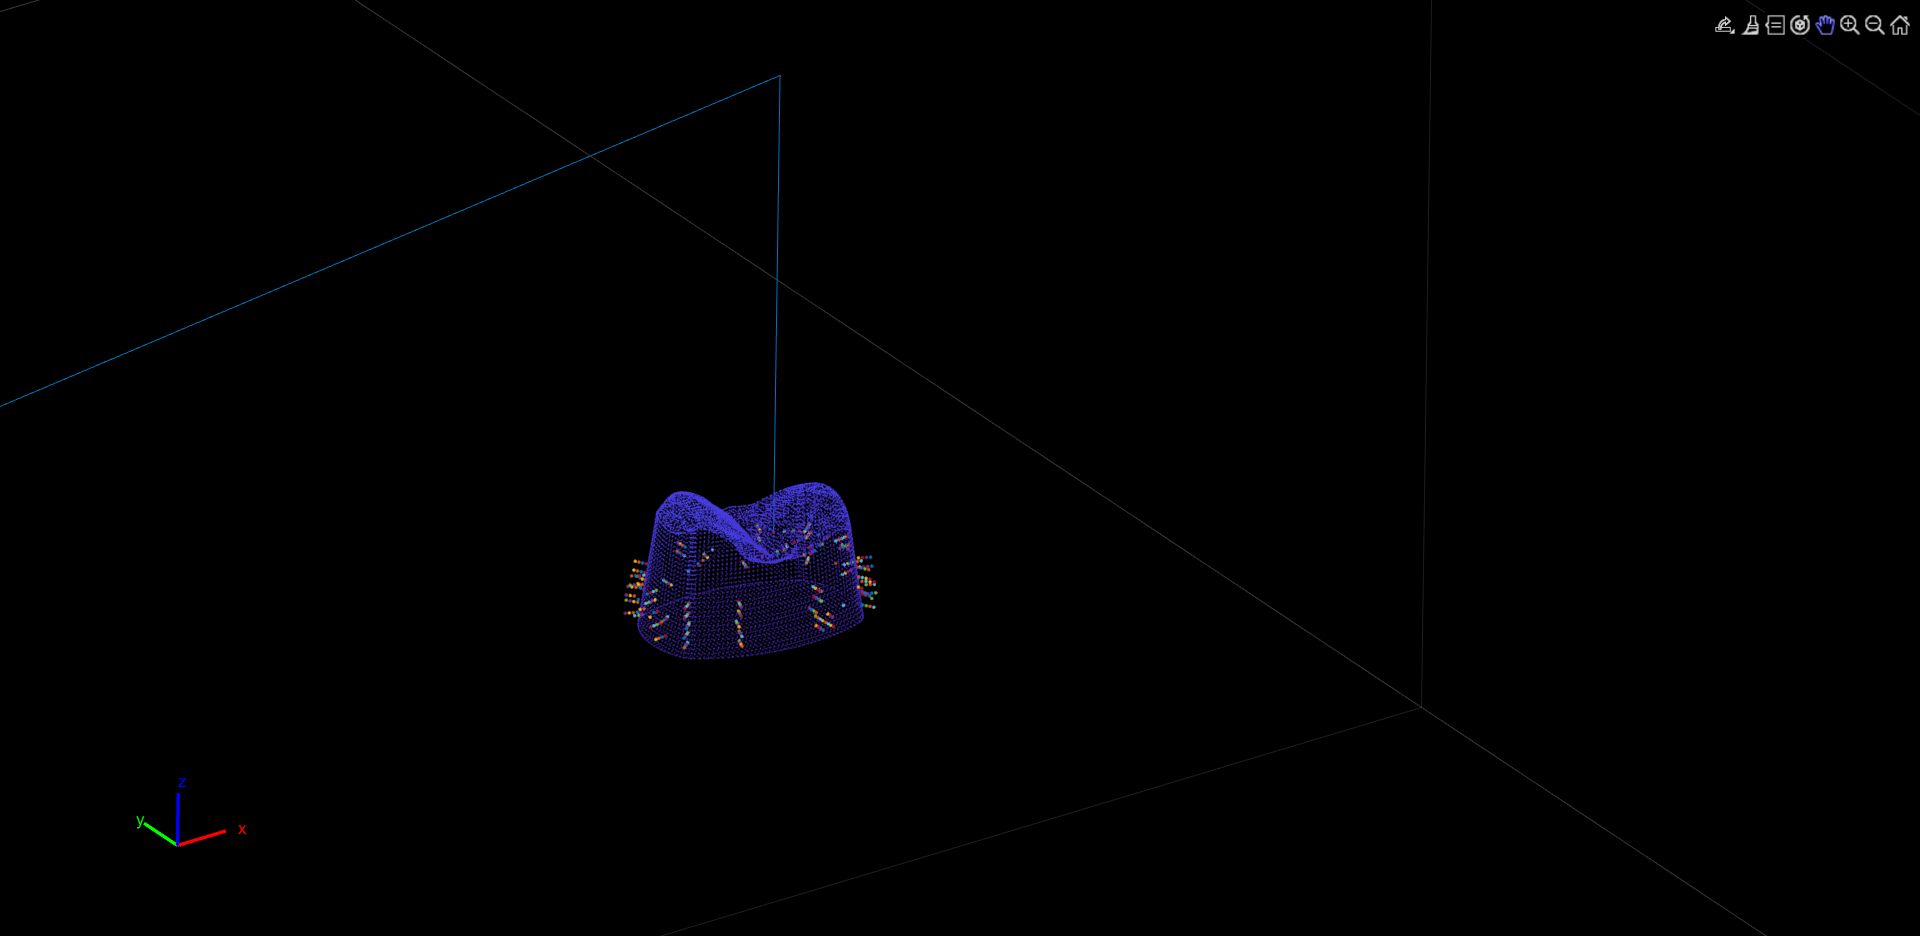

[minimum,ind,ee_arr] = min2pts(dental,q_tot,ptCloud_fin);

figure
pcshow(ptCloud_fin)
hold on
show(dental,home,'PreservePlot',false);
hold on
% plotQuarter(q1_traj_arr); hold on
% plotQuarter(q2_traj_arr); hold on
% plotQuarter(q3_traj_arr); hold on
% plotQuarter(q4_traj_arr); hold on
plotClosest(dental,q_tot,ee_arr,ind,ptCloud_fin);

% plotClosest(dental,q2_config,ee_arr,ind,ptCloud_fin);
% plotClosest(dental,q3_config,ee_arr,ind,ptCloud_fin);


## `Helper Functions`

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
%     curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end

### `Closest Point Function:`

function [minimum,ind,ee_arr] = min2pts(bot,traj,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(traj(1,:)));
    ee_arr = zeros(length(traj(1,:)),3);
    
    for i = 1:1:length(traj(1,:))
        transform = getTransform(bot,traj(:,i),'Body7','base');
        ee = transform(1:3,4);
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

### `Plot Distance between ee and closest point function:`

function [] = plotClosest(bot,traj,ee_arr,ind,ptCloud)
    fps = 10;
    r = rateControl(fps);
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    axis([-300 400 -300 300 -200 200])
    for i = 1:1:length(traj(1,:))
        show(bot,traj(:,i),'PreservePlot',false);
        drawnow
        waitfor(r);
        hold on
%         line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)],'Color','w')
        plot3(ee_arr(i,1),ee_arr(i,2),ee_arr(i,3),'Marker','.');
    end
    
end

### `Order Trajectory based on quarters:`

function [q_traj_arr] = orderQuarter(q_arr)
    %Construct q1 trajectory
    %Start from upper and outer contour
    len_q_z = length(q_arr(:,1)) - 2; %Exclude upper two bc top of tooth
    len_q_c = length(q_arr(1,:)); %Number of contours
    
    
    for j = 0:len_q_c-1 %Different contours
        for i = 0:len_q_z-1 %Different z levels
            q_traj = q_arr{len_q_z-i,len_q_c-j};
            if j == 0 && i == 0 %Need to initialize q1_traj_arr
                q_traj_arr = q_traj;
            else
                if mod(i,2) ~=0  %Reverse every other path
                    q_traj = flipud(q_traj);
                end
                q_traj_arr = vertcat(q_traj_arr,q_traj); %Append to bottom of array
            end
        end
    end
end

### `Plot Quarter Trajectory:`

function [] = plotQuarter(q_traj_arr)
    labels = cellstr( num2str([1:length(q_traj_arr(:,1))]') );
    
    plot3(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3),"LineWidth",1);
    text(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3), labels, 'VerticalAlignment','bottom', ...
                                 'HorizontalAlignment','right')
end

### `Finding Home Config`

function homeConfig = findHomeConfig(ptCloud_fin)
    x_max = max(ptCloud_fin.Location(:,1));
    x_min = min(ptCloud_fin.Location(:,1));
    y_max = max(ptCloud_fin.Location(:,2));
    y_min = min(ptCloud_fin.Location(:,2));
    x = (x_max + x_min)/2;
    y = (y_max + y_min)/2;
    z = -0.04;
    homeConfig = [x y z];
end

### `Check if path in collision or not`

function isTrajectoryInCollision = isInCollision(q, collisionMesh, robot)
    worldCollisionArray = {collisionMesh};
%     ik = inverseKinematics("RigidBodyTree",robot);
%     weights = ones(1,6);
%     
    rng(0); % start with a fixed seed to get repeatable results.
%     startConfig = ik("Body5",startPose,weights,robot.homeConfiguration);
%     endConfig = ik("Body5",endPose,weights,robot.homeConfiguration);
%     
%     
%     t = 200;
%     q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],t,"EndTime",2);
    
    % Initialize outputs
    inCollision = false(length(q), 1); % Check whether each pose is in collision
    worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
    
    for i = 1:length(q)
        
        [inCollision(i),sepDist] = checkCollision(robot,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
        
        [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
        worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
        worldCollisionPairIdx{i} = worldCollidingPairs;
        
    end
    
    %see if there is any collision
    isTrajectoryInCollision = any(inCollision);
end